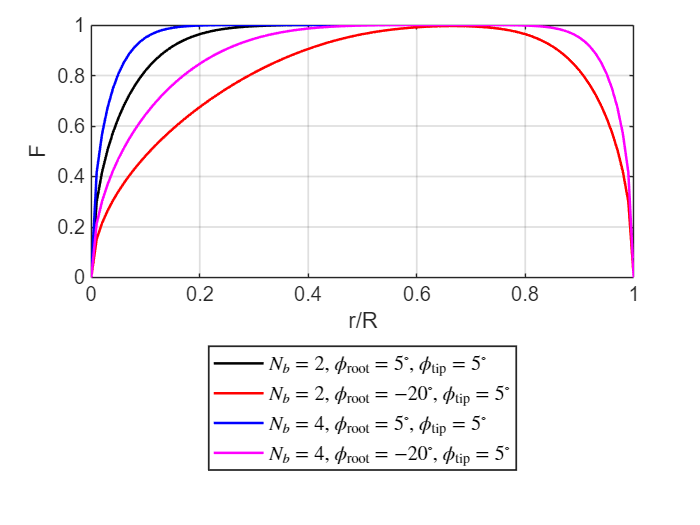

clc; clear; close all;

% Vetor radial e parâmetros do rotor/pá
rr = 0:0.01:1;  
BLADE.Span = 1; 
BLADE.RootBladeDistance = 0;  

% Posição das seções ao longo da pá
pos = [zeros(1, length(rr)); rr; zeros(1, length(rr))]; 
BLADE.pos_sec = pos;  

phi_tip = [5 5];
phi_root = [5 -20];  

F_prandtl = zeros(length(phi_root), length(rr));  
lg = {};  

% Cores: preto, vermelho, azul, roxo
cores = {'k', 'r', 'b', 'm'};

figure('Color', 'w'); 
hold on;

k = 1;
for n = 2:2:4
    ROTOR.Nb = n;  
    for j = 1:length(phi_tip)     
        str = sprintf('$N_b = %d$, $\\phi_{\\mathrm{root}} = %d^\\circ$, $\\phi_{\\mathrm{tip}} = %d^\\circ$', ...
                      n, phi_root(j), phi_tip(j));
        lg{end+1} = str;    
    
        F_prandtl(k, :) = prandtl_function(phi_root(j), phi_tip(j), ROTOR, BLADE); 
        plot(rr, F_prandtl(k, :), 'Color', cores{k}, ...
             'LineWidth', 1.5, ...
             'DisplayName', str);
        k = k + 1; 
    end  
end

% Eixos, título, legenda
xlabel('r/R', 'FontSize', 12);
ylabel('F','FontSize', 12);

xlim([0 1]); ylim([0 1]);
grid on;

legend(lg, 'Interpreter', 'latex', 'Location', 'southoutside', ...
       'Orientation', 'vertical', 'FontSize', 12);
set(gca, 'FontSize', 12, 'Box', 'on', 'LineWidth', 1);

% Salvar como EPS
saveas(gcf, '.\studies\tip_losses\prandtltiplossfunction.eps', 'epsc');